N = 8;
n = 0:(N-1);
[matrixK,matrixN] = meshgrid(n,n);
M = matrixK.*matrixN;
FFTmatrix = exp(-1j*2*pi/N*(M));% 创建FFT矩阵

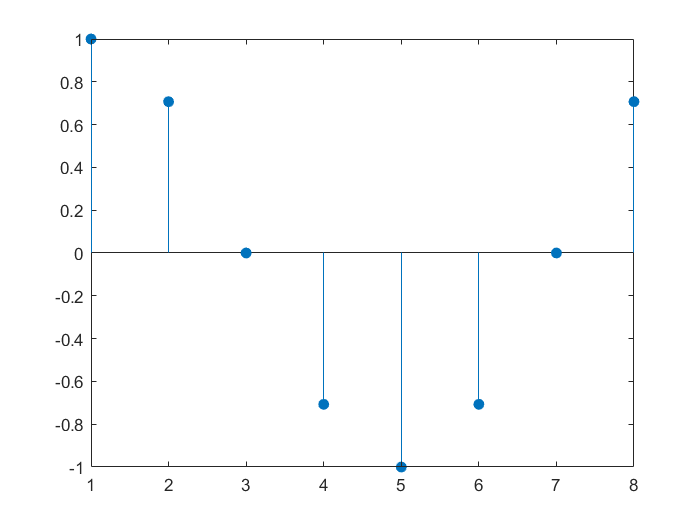

f = 1; % 数字频率，在采样范围内完整经过了多少周期
y = cos(2*pi*f*n/N);%  输入信号的表达式，可以任意取
% y = exp(1i*(2*pi*f*n/N));
% y = exp(1i*(2*pi*f*n/N + pi/4));
figure;
stem(y,'filled');

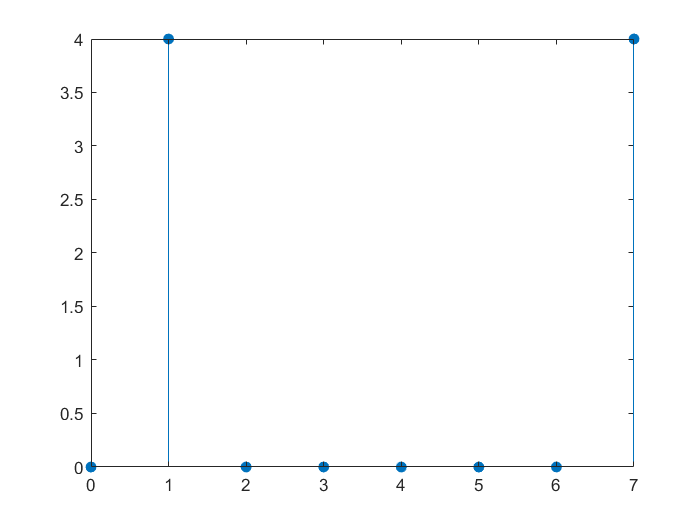

f1 = FFTmatrix * y.';
f11 = fft(y); % 分别用矩阵和调包实现FFT
stem(0:(N-1),abs(f11),'filled');

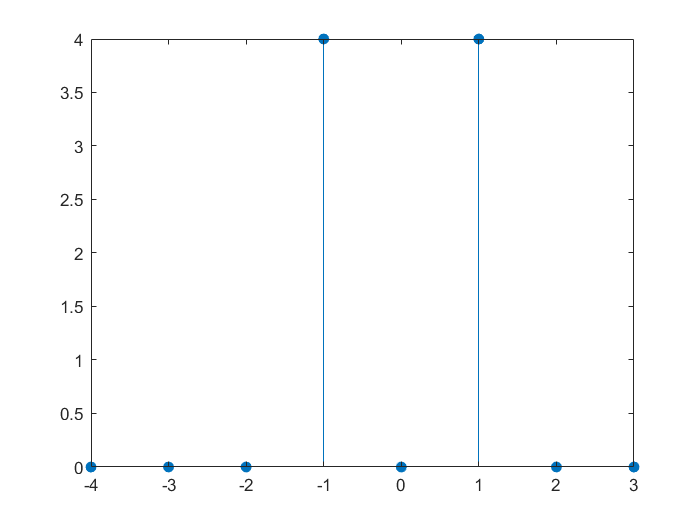

stem((-4:3),fftshift(abs(f11)),"filled");

% % 用for循环实现FFT，并且绘制复平面上的旋转
% XK = zeros(1, N);
% for k = 1 % 想看哪一项的相位校正过程，就把k设置为几
%     figure;
%     s = zeros(1, N);
%     s_p = y;  % 初始化为零以便于绘图
%     h = compass(0);  % 创建空的 compass 图并获取句柄
%     
%     for j = 0:N-1  % 从 0 到 N-1 循环
%         XK(k+1) = XK(k+1) + exp(-1j * (2 * pi * k * j) / N) * y(j+1);
%         s(j+1) = exp(-1j * (2 * pi * k * j) / N) * y(j+1);
%         
%         % 每次更新箭头位置，并绘制当前第 j 个箭头
%         s_p(j+1) = s(j+1);
%         
%         % 清除之前的图像并重新绘制箭头
%         delete(h);  % 删除上一帧的箭头
%         h = compass(s_p);  % 绘制更新后的箭头
%         
%         % 获取箭头末端的位置
%         x_end = real(s(j+1));
%         y_end = imag(s(j+1));
%         
%         % 在箭头末端显示其值（幅度和相位）
%         magnitude = abs(s(j+1));
%         angle_deg = rad2deg(angle(s(j+1)));  % 将相位转换为角度
%         text(x_end, y_end, sprintf('%.2f ∠ %.2f°', magnitude, angle_deg),...
%             'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
%         
%         
%         pause(2);  % 动画暂停时间
%     end
%     
%     disp('每一项相位校正后的结果：')
%     disp(num2str(transpose(s)));  % 显示当前的 s
%     disp('该项频谱的大小，即上一个数组求和：')
%     disp(num2str(XK(k+1)));  % 显示当前的 XK(k+1)
%     disp('该项频谱的模：')
%     disp(num2str(abs(XK(k+1))));% 显示频谱的模
% end

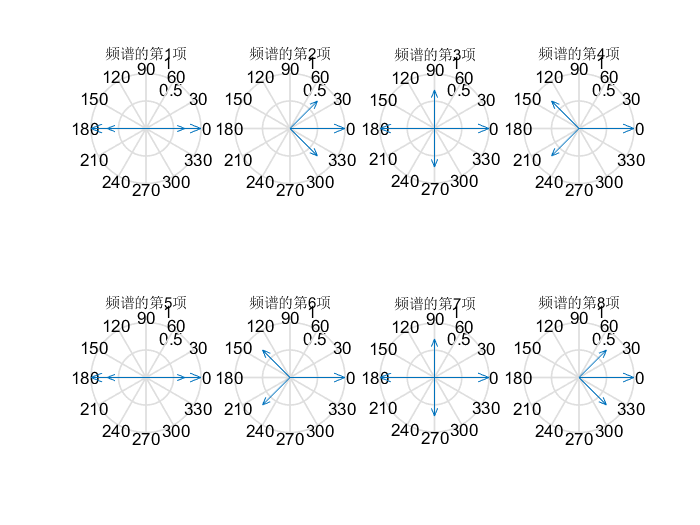

% 用for循环实现FFT，并且绘制复平面上的旋转
XK = zeros(1, N);
figure;
for k = 0:N-1 % 想看哪一项的相位校正过程，就把k设置为几
    subplot(2,4,k+1);
    compass(y);
    title(['频谱的第',num2str(k+1),'项']);
    pause(0.5);
    s = zeros(1, N);
    for a = 0:0.02:1
        for j = 0:N-1  % 从 0 到 N-1 循环
            XK(k+1) = XK(k+1) + exp(-1j * a * (2 * pi * k * j) / N) * y(j+1);
            s(j+1) = exp(-1j * a * (2 * pi * k * j) / N) * y(j+1);
        end
        compass(s);
        title(['频谱的第',num2str(k+1),'项']);
         pause(0.001);
    end
    pause(0.5);

end